#### **BI2009B **Procesamiento de imágenes médicas para el diagnóstico

# Mathematical Morphology

07/04/22

**Team Members:**

**Maxine Annel Pacheco Ramírez A01551933**

**Kristen Aideé Pérez Alvarez A00829551**

**Dacia Martínez Díax A01733799**

**René Jahaziel Rangel Yáñez A00826919**

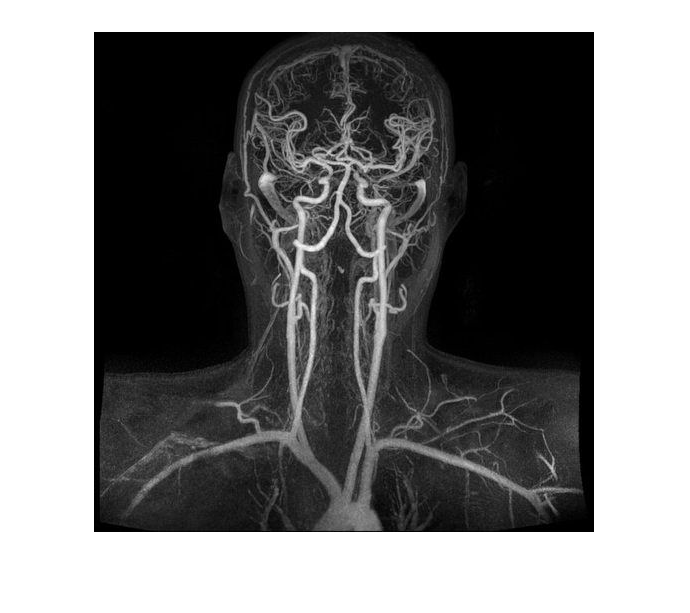

%Select image file to analize
f=imread('vessels.jpeg');
%f=imread('radiograph1.jpg');
%f=imread('Normal_R_Hand_jumbo.jpeg');
%f=imread('coronary-angiogram.jpg');

f=double(f(:,:,1)); %Convert to double in order to set greyscale
f=f/max(max(f)); %Normalize values
%f=imresize(f,0.5);
figure(1)

%f=max(max(f))-f;
imshow(f,[]); %Display the image

## Dilatation

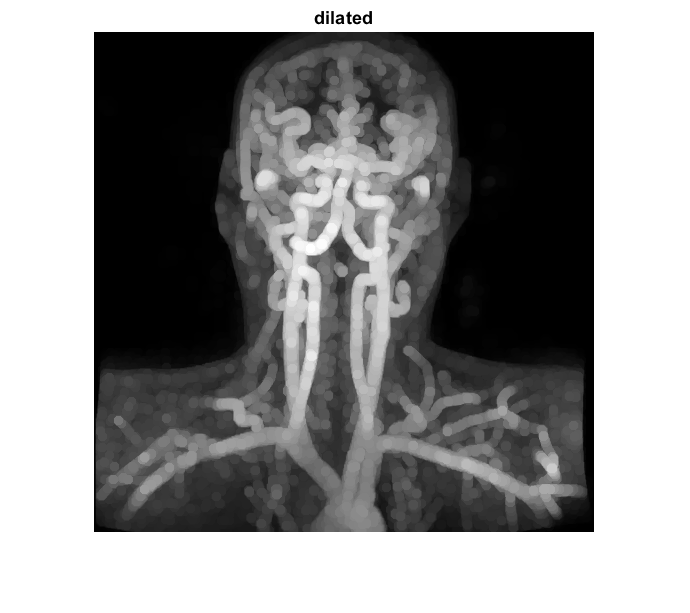

se = strel('disk',5);
BW2 = imdilate(f,se);
imshow(BW2), title('dilated')

% Use different disk size

## Erosion

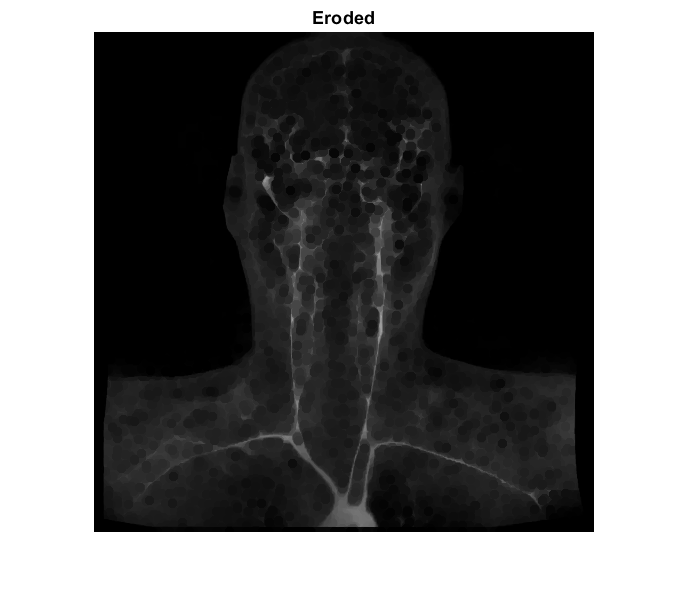

se = strel('disk',5);
BW3 = imerode(f,se);
imshow(BW3), title('Eroded')

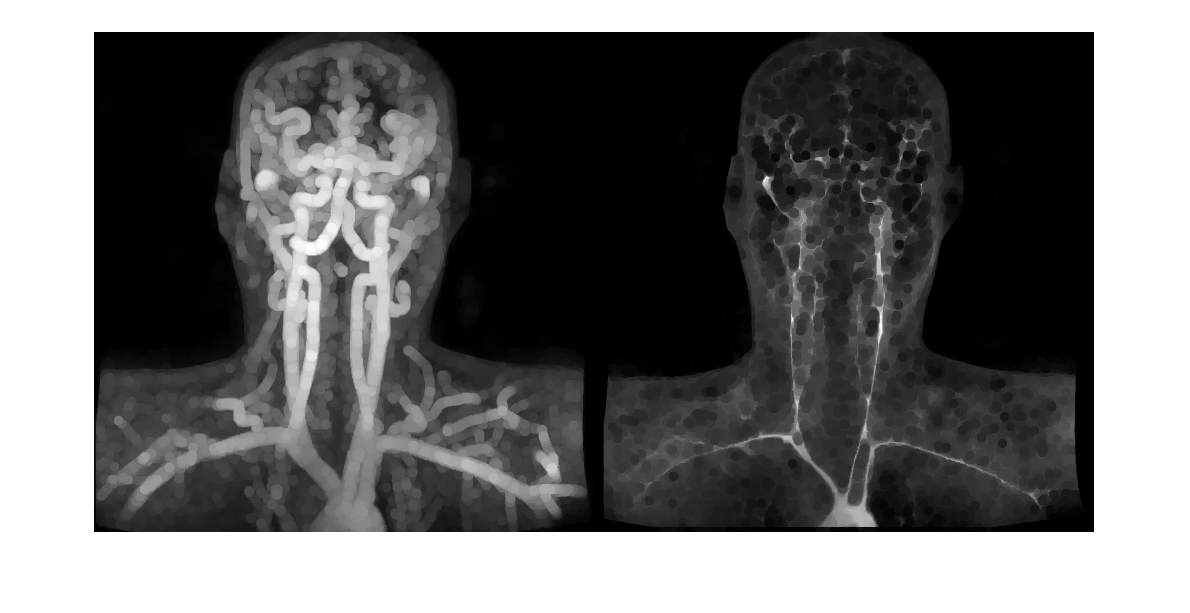

% Use different disk size
imshowpair(BW2,BW3,'montage')

## Opening

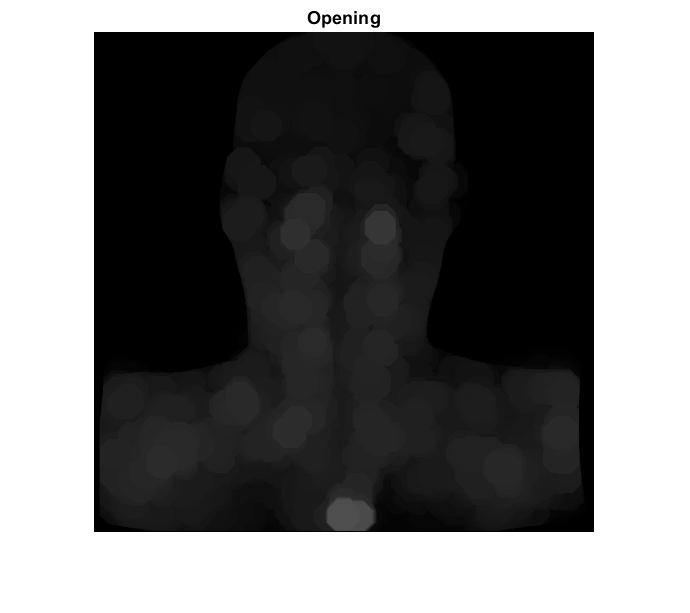

se = strel('disk',15);
BW2 = imopen(f,se);
imshow(BW2), title('Opening')

% Use different disk size

## Closing

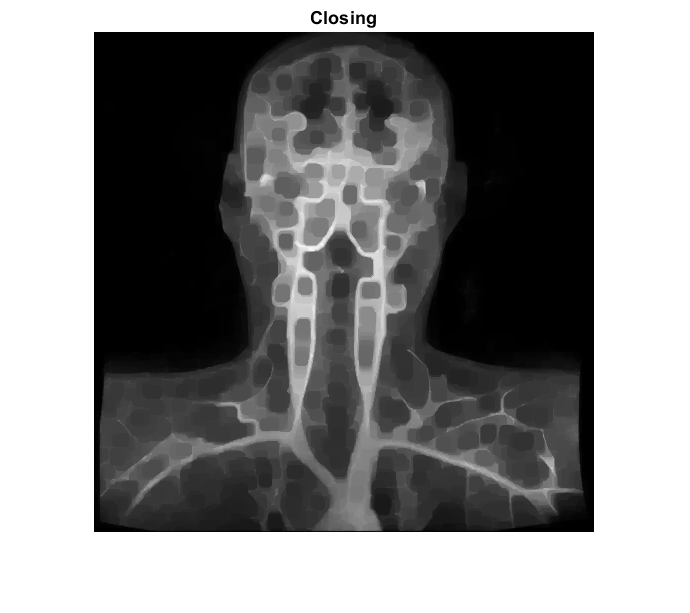

se = strel('disk',7);
BW2 = imclose(f,se);
imshow(BW2), title('Closing')

% Use different disk size

## Gradient

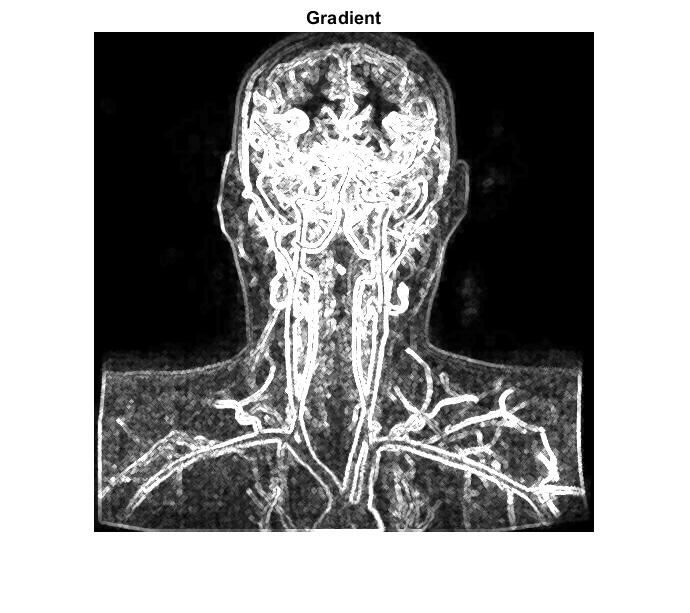

se = strel('disk',2);
BW1 = imdilate(f,se) - imerode(f,se);
imshow(BW1,[0,0.25]), title('Gradient')

%colormap('jet')
% Use different disk size


## Preprocess the Image The Rice Matlab Example

Read an image into the workspace.

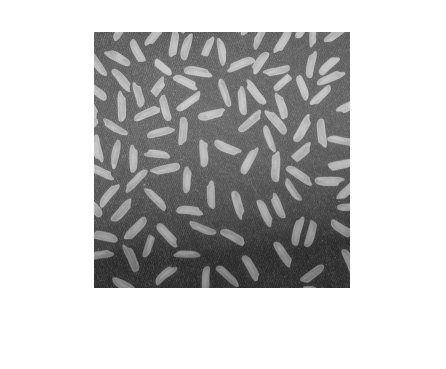

I = imread('rice.png');
%I = f;
imshow(I)

The background illumination is brighter in the center of the image than at the bottom. Preprocess the image to make the background illumination more uniform.

As a first step, remove all of the foreground (rice grains) using morphological opening. The opening operation removes small objects that cannot completely contain the structuring element. Define a disk-shaped structuring element with a radius of 15, which fits entirely inside a single grain of rice.

se = strel('disk',15)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [29×29 logical]
    Dimensionality: 2


To perform the morphological opening, use `imopen` with the structuring element.

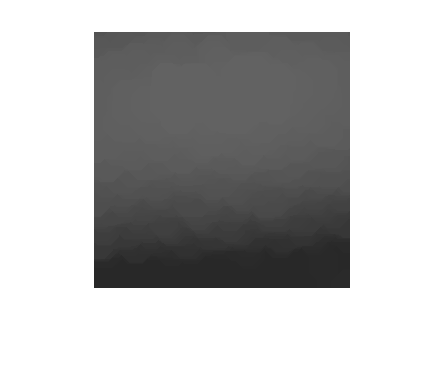

background = imopen(I,se);
imshow(background)

Subtract the background approximation image, `background`, from the original image, `I`, and view the resulting image. After subtracting the adjusted background image from the original image, the resulting image has a uniform background but is now a bit dark for analysis.

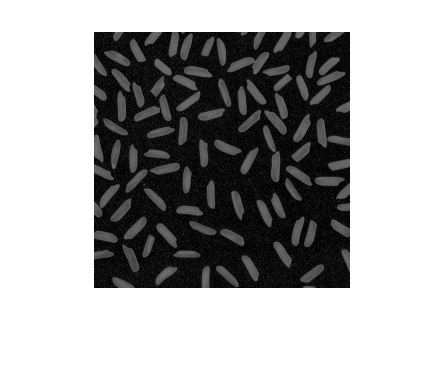

I2 = I - background;
imshow(I2)

Use `imadjust` to increase the contrast of the processed image `I2` by saturating 1% of the data at both low and high intensities and by stretching the intensity values to fill the `uint8` dynamic range.

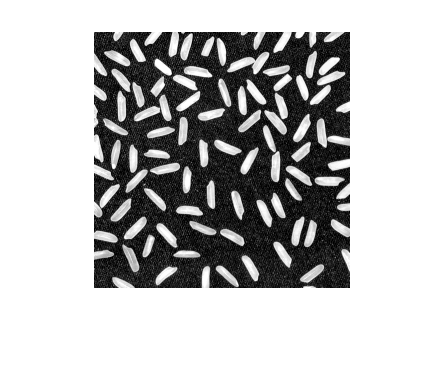

I3 = imadjust(I2);
imshow(I3)

Note that the prior two steps could be replaced by a single step using `imtophat` which first calculates the morphological opening and then subtracts it from the original image.

`I2 = imtophat(I,strel('disk',15));`

Create a binary version of the processed image so you can use toolbox functions for analysis. Use the `imbinarize` function to convert the grayscale image into a binary image. Remove background noise from the image with the `bwareaopen` function.

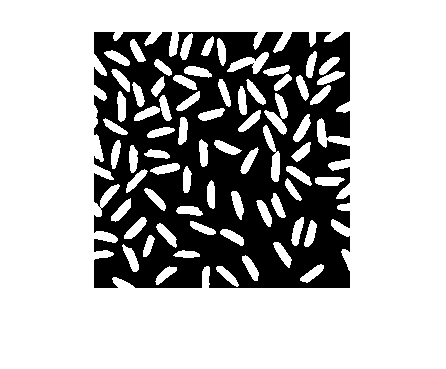

bw = imbinarize(I3);
bw = bwareaopen(bw,50);
imshow(bw)


% Use different size of the structural element


# Skeletonize 2-D Grayscale Image

Read a 2-D grayscale image into the workspace. Display the image. Objects of interest are dark threads against a light background.

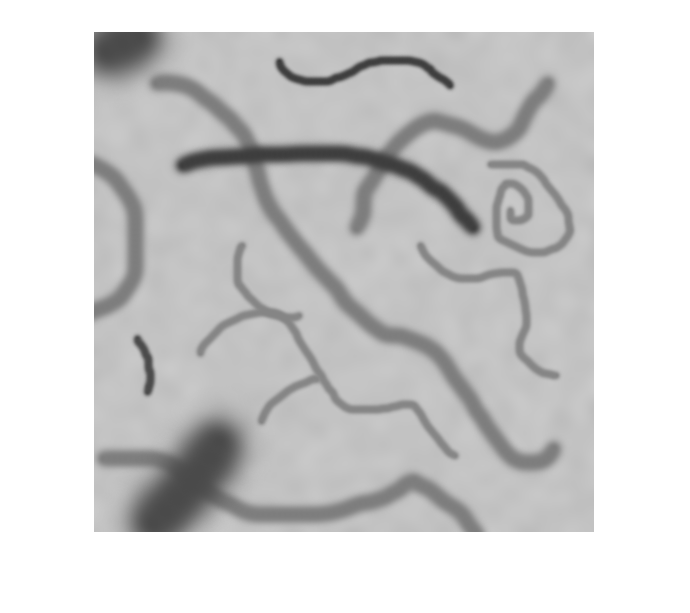

I = imread('threads.png');
imshow(I)

Skeletonization requires a binary image in which foreground pixels are `1` (white) and the background is `0` (black). To make the original image suitable for skeletonization, take the complement of the image so that the objects are light and the background is dark. Then, binarize the result.

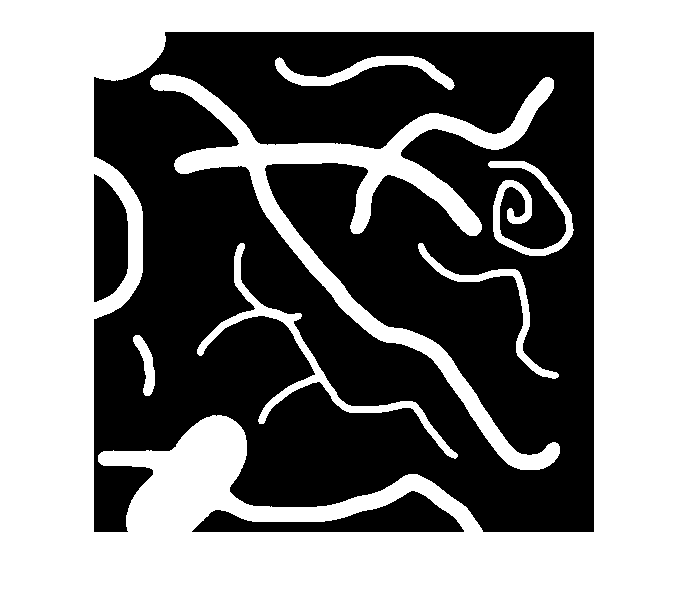

Icomplement = imcomplement(I);
BW = imbinarize(Icomplement);
imshow(BW)

Perform skeletonization of the binary image using `bwskel`.

out = bwskel(BW);

Display the skeleton over the original image by using the `labeloverlay` function. The skeleton appears as a 1-pixel wide blue line over the dark threads.

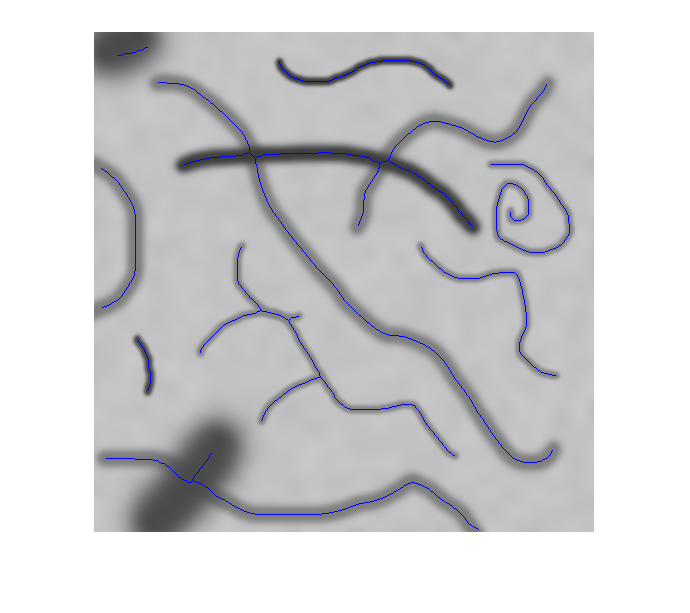

imshow(labeloverlay(I,out,'Transparency',0))

Prune small spurs that appear on the skeleton and view the result. One short branch is pruned from a thread near the center of the image.

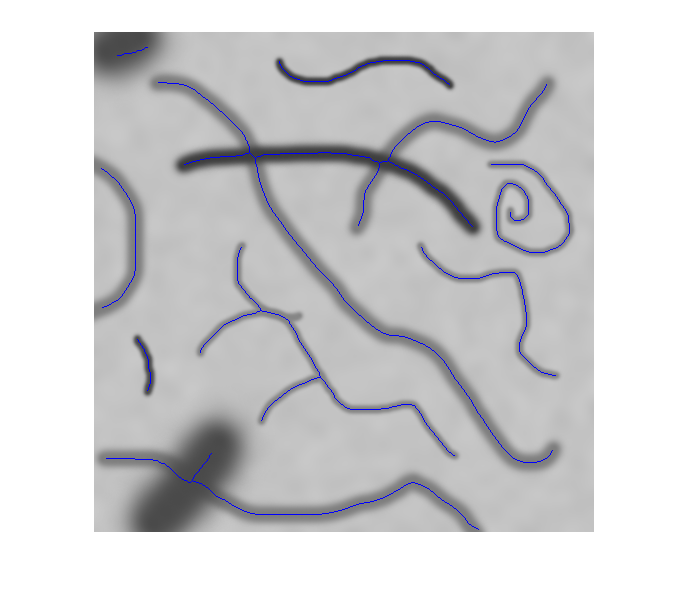

out2 = bwskel(BW,'MinBranchLength',15);
imshow(labeloverlay(I,out2,'Transparency',0))

%Play with the size of Min Branch Lenght


## The alternative method with bwmorph

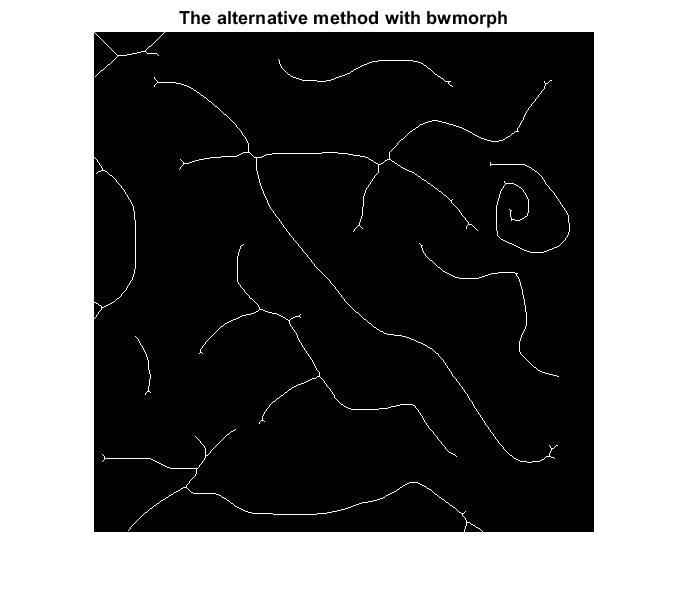

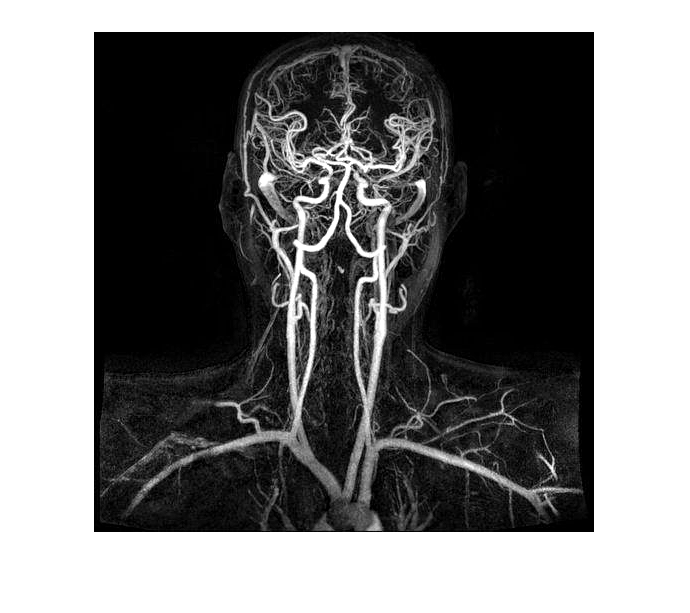

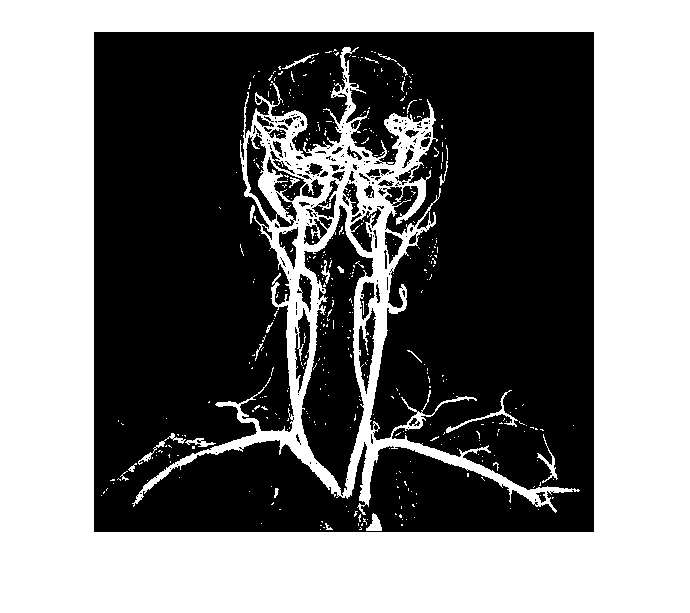

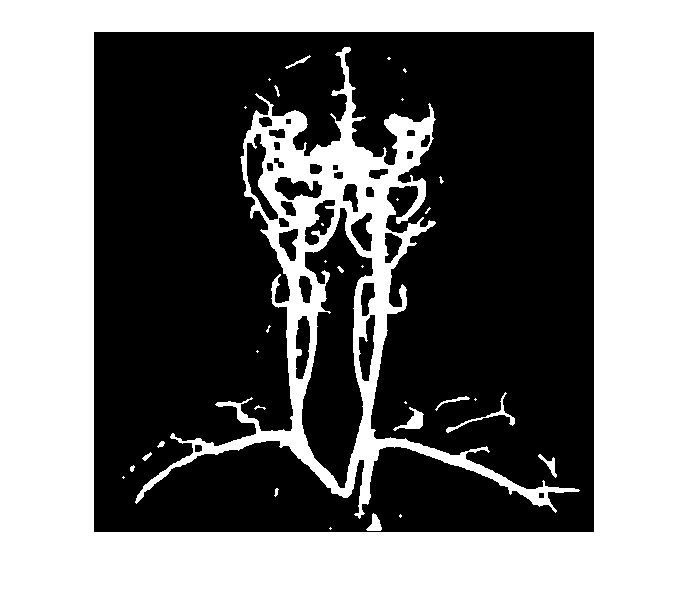

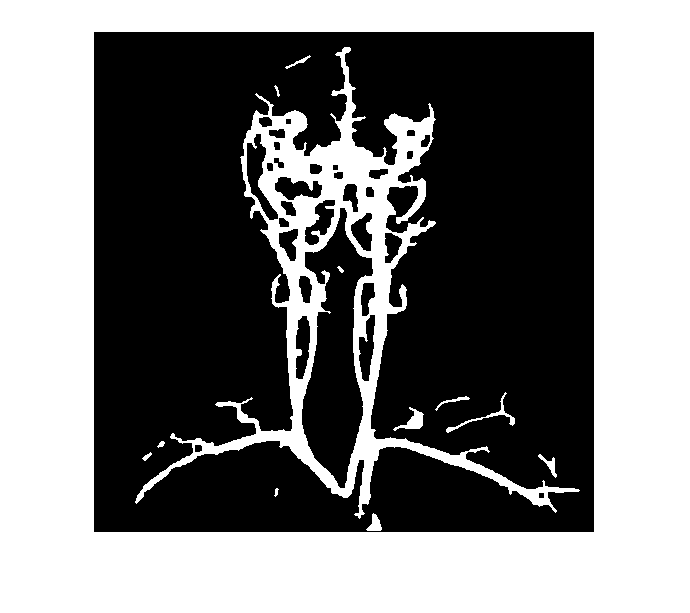

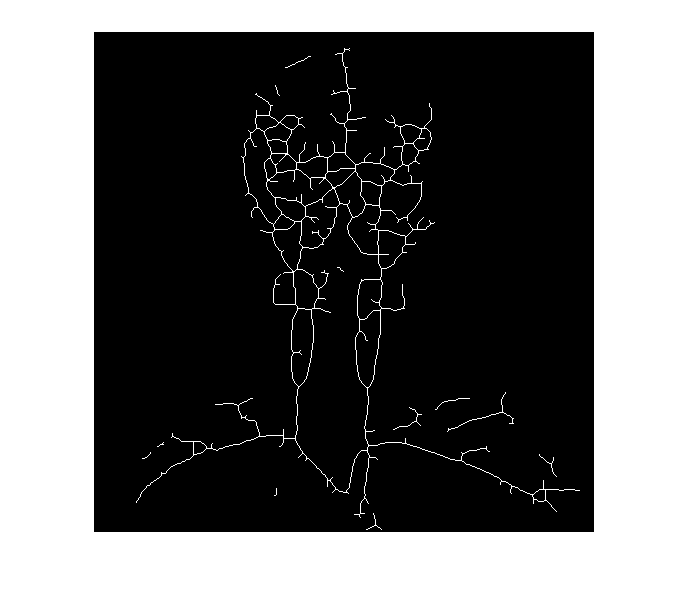

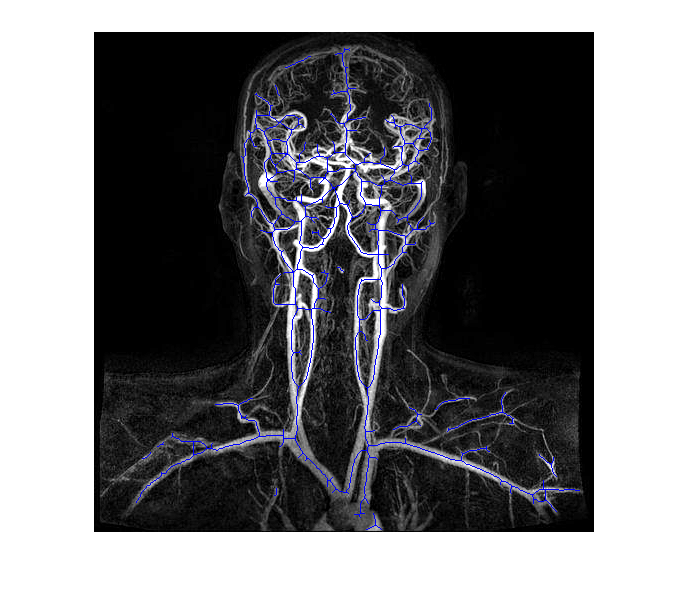

BW3 = bwmorph(BW,'skel',Inf); %Se utiliza la funcion skel con n= infinito.

%cuando el último parámetro es igual a infinito, se eliminan los pixeles en
%las fronteras de los objetos, sin permitir que estos se sepaeren.
figure
imshow(BW3)
title('The alternative method with bwmorph')

## Lets play with the x-ray

%se = strel('disk',15);  %In this case we changed the param
se = strel('disk',7);  %In this case we changed the parameter of radio from 15 to 7. 
%SE = strel(shape,parameters)
BW3 = f-imopen(f,se);
angio = BW3;
angio = imadjust(angio);
imshow(angio,[])
title('with disk=7')

bw = imbinarize(BW3); %imbinarize crea una imagen binaria a partir de una imagen 2D o 3D en escala de grises
imshow(bw,[])
bw = imopen(bw,strel('disk',1));
%se hace uso de la opción open para dilatación.
bw = imclose(bw,strel('disk',3));
%Se hace uso de la opción close para erosion
imshow(bw,[])
title('Imágen después de pasar por Dilatación y Erosión')

bw = bwareaopen(bw,25); %elimina todos los componentes conectados que tienen menos de P píxeles de la imagen binaria BW
imshow(bw,[])
title('Imágen después de pasar por bwareopen')

BW3 = bwmorph(bw,'skel',Inf); %aplica una operación morfológica específica a la imagen binaria.
imshow(BW3)
title('Imágen después de pasar por skel')
%En esta parte logramos tener un esqueleto de la imágen. 

imshow(labeloverlay(angio,BW3,'Transparency',0)) %utiliza la imagen de entrada con un color donde la máscara BW es verdadera. 


% Do the same with your own image [Image called vessels]